data = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/COVID/CC_COVID/Confirmed_Cases_CC.csv', 'ReadVariableNames',1);
dates = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/COVID/CC_COVID/Confirmed_Cases_CC.csv');

dates = table2array(dates(1,[12:173]));
dates = datetime(dates, 'Format', 'dd/MM/yy'); 

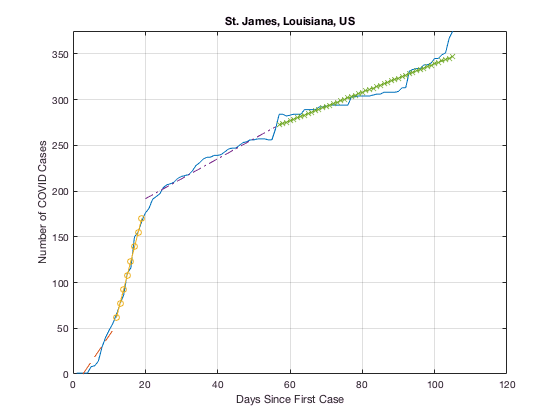

%slopes = [];
%for t = 1:height(data)
    t=304;
    cases = table2array(data(t,12:173));
    cases = nonzeros(cases); % non-zero cases 
    x = [1:length(cases)]'; % number of days since first case 
    
    plot(x,cases)
    grid on;
    hold on;
    ylim([0,max(cases)])
    ylabel('Number of COVID Cases')
    xlabel('Days Since First Case')
    title(data.Combined_Key(t));
    
    case1 = cases(cases<=max(cases)*0.15);
    x1 = x(cases<=max(cases)*0.15);
    if ~isempty(x1)
        [m1,b1]=line_fit(x1,case1);
        fit1 = (m1.*x1)+b1;
        plot(x1,fit1,'--')
    end 
    
    case2 = cases((cases>max(cases)*0.15)&(cases<max(cases)*0.45));
    x2 = x((cases>max(cases)*0.15)&(cases<max(cases)*0.45));
    if ~isempty(x2)
        [m2,b2] = line_fit(x2,case2);
        fit2 = (m2.*x2)+b2;
        plot(x2,fit2,'-o')
    end 
    
    case3 = cases((cases>max(cases)*0.45)&(cases<max(cases)*0.75));
    x3 = x((cases>max(cases)*0.45)&(cases<max(cases)*0.75));
    if ~isempty(x3)
        [m3,b3] = line_fit(x3,case3);
        fit3 = (m3.*x3)+b3;
        plot(x3,fit3,'-.')
    end 
    
    case4 = cases(cases>=max(cases)*0.75);
    x4 = x(cases>=max(cases)*0.75);
    if ~isempty(x4)
        [m4,b4] = line_fit(x4,case4);
        fit4 = (m4.*x4)+b4; 
        plot(x4,fit4,'-x')
    end 
    %m = [m1, m2, m3, m4];
    %slopes = [slopes;m];
%end 
hold off;

S = array2table(slopes, 'VariableNames', {'Slope1','Slope2','Slope3','Slope4'});
S.County = data.Admin2;
S.State = data.Province_State;

writetable(S,'/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/Cases_Slopes.csv')

function[m, b] = line_fit(x, y)
    Mx = mean(x); 
    My = mean(y);
    sx= std(x); 
    sy = std(y); 
    r = corr(x,y);
    
    m = r*(sy/sx);
    b = My-m*Mx;
end 